Forår2017Mat

clearvars
clc
close all

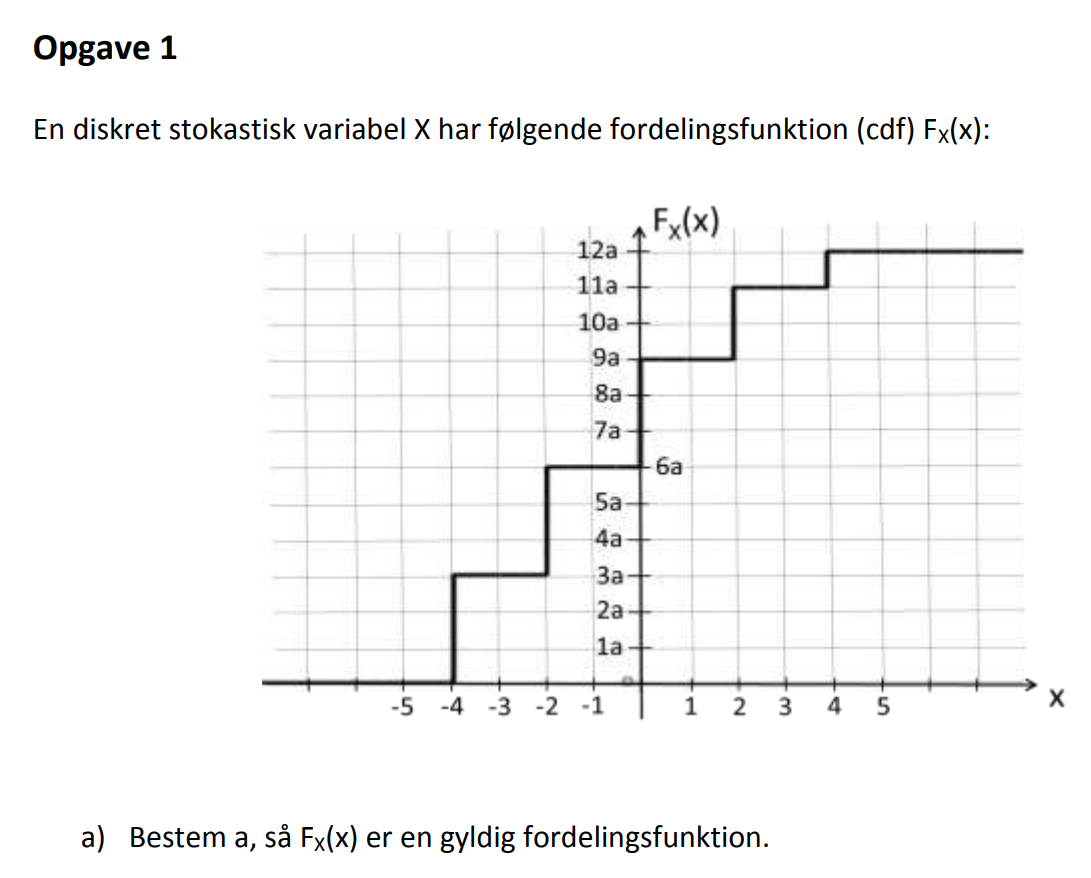

clearvars

fx = [3/12 3/12 3/12 2/12 1/12];
x = [-4 -2 0 2 4];
 
figure(1);
bar(x,fx);

sum(fx)

ans = 1

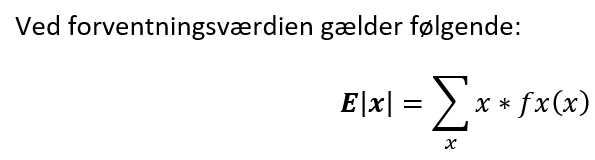

middel = sum(x.*fx)

middel = -0.8333

var = sum(x.^2.*fx)-middel^2

var = 6.3056

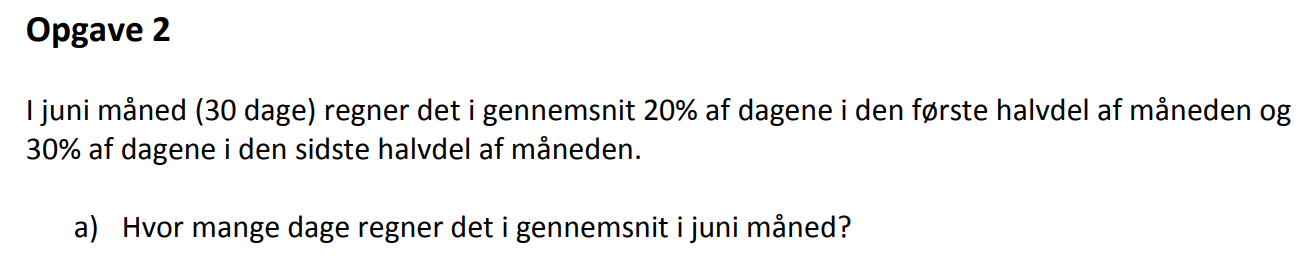

hændelse a. Regner i starten af juni.

Hændelse b. Regner i slutnigen af juni.

Pr_R_Forst = 0.2;
Pr_R_Sidst = 0.3;
Pr_Forst = 0.5;
Pr_Sidst = 0.5;
Juni_Dage = 30;
total_prop = Pr_R_Forst*Pr_Forst + Pr_R_Sidst * Pr_Sidst

total_prop = 0.2500

gennemsnitRegn = 30*total_prop

gennemsnitRegn = 7.5000

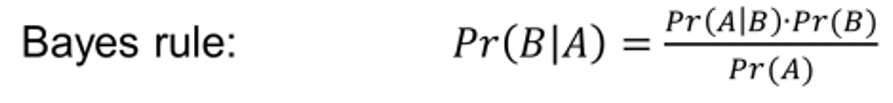

Pr_R_Sidst*Pr_Sidst/total_prop

ans = 0.6000

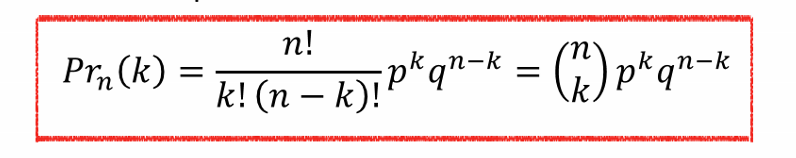

Pr_IkkeRegn_forst = 1-Pr_R_Forst

Pr_IkkeRegn_forst = 0.8000

(15/1)*Pr_R_Forst^1*Pr_IkkeRegn_forst^14

ans = 0.1319

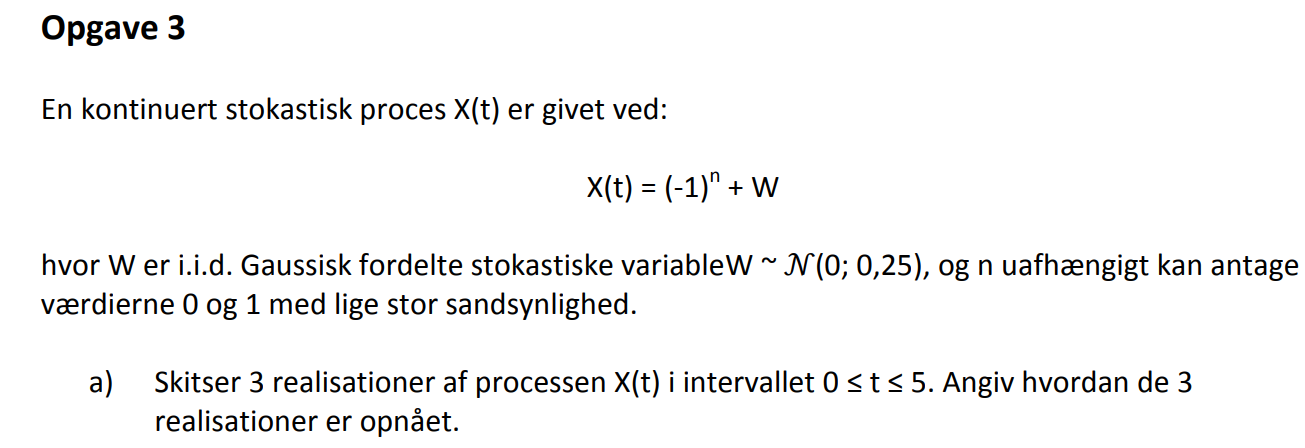

clearvars
close all
x = 0:1:5;
realisationer = 3;
% Først få værdierne til n
n = randi([0, 1], 1, 3)

n =      0     0     1


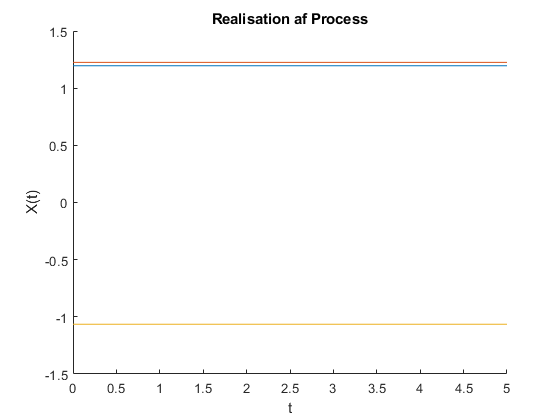

% Ud fra W~N(0; 0,25) kan vi udlede:
mean = 0; variance = 0.25; sigma = sqrt(variance);
clear mean
% Få værdierne til w
w = randn(1, 3) * sigma;
figure(1)
hold on
xlabel("t"); ylabel("X(t)"); title("Realisation af Process");
for i = 1:realisationer
    y = (-1)^n(i) + w(i);
    plot(x, ones(1,length(x))*y);
    
end

mean = mean(y)

mean = -1.0651

variane = var(y)

variane = 0

middel = (-1)^0*(1/2)+(-1)^1*(1/2)+0

middel = 0

middel2 = ((-1)^0)^2*(1/2)+((-1)^1)^2*(1/2)+0

middel2 = 1

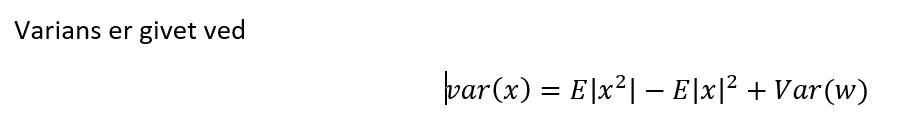

variance = middel2-middel^2+0.25

variance = 1.2500

Da processen er uafhængig af tiden, og at middelværdien og variansen ikke ændrer sig over tid, så kan vi konstanter at processen er stationær.

Processen er ikke ergodisk da pmf ikke kan bestemmes udfra en realisation

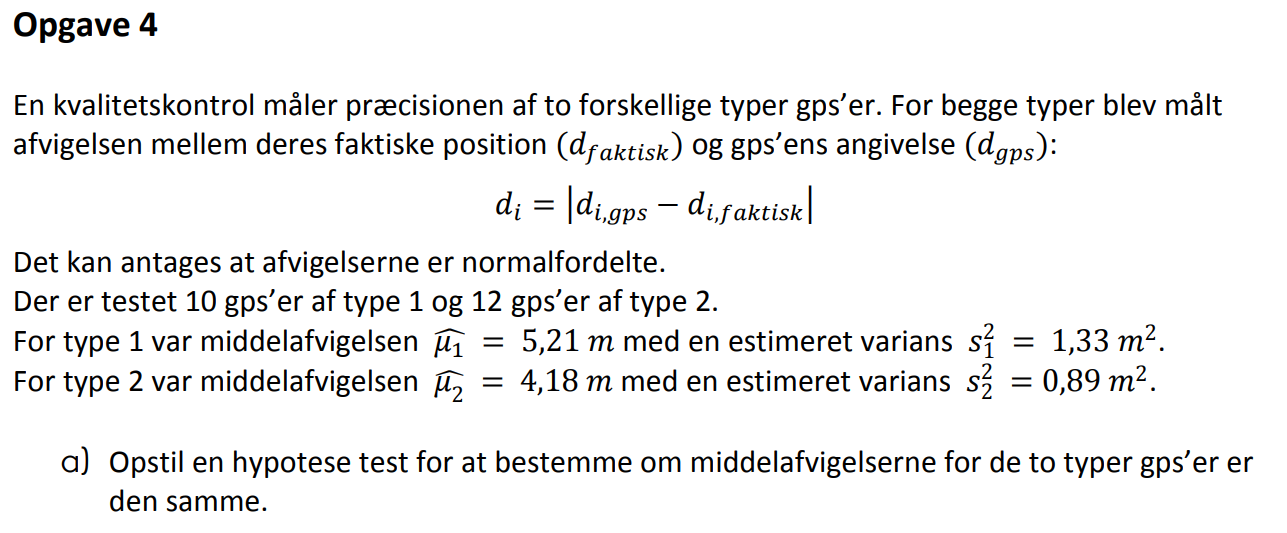

Null hypothesis. Brugt som testen af ingen forskel.


$$H_0 =\mu 1=\mu 2$$


Alternanive hypotese


$$H_1 =\mu 1\not= \mu 2$$


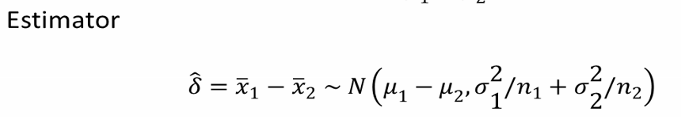

middel= abs(5.21-4.18)

middel = 1.0300

n1 = 10;
n2 = 12;
s1_2= 1.33;
s2_2 = 0.89;
standard2=1/(n1+n2-2)*((n1-1)*s1_2+(n2-1)*s2_2)

standard2 = 1.0880

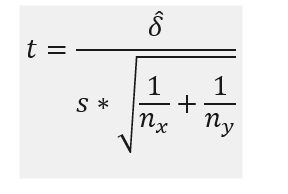

t = middel/(sqrt(standard2)*sqrt((1/n1)+(1/n2)))

t = 2.3062

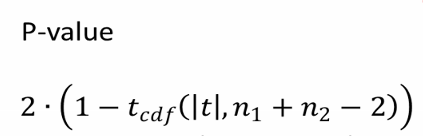

pval = 2*(1-tcdf(abs(t),(n1+n2)-2))

pval = 0.0319

Da p er mindre end 0.05 så kan vi afvise hypotese 0.

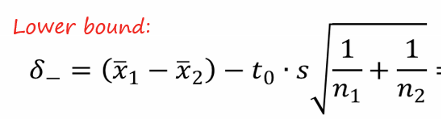

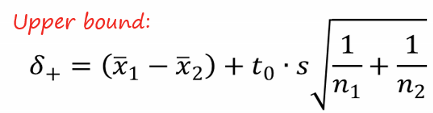

t0=tinv(1-0.05/2,(n1+n2-2))

t0 = 2.0860

koefMinus = middel-t0*sqrt(standard2)*sqrt((1/n1)+(1/n2))

koefMinus = 0.0984

koefPositiv = middel+t0*sqrt(standard2)*sqrt((1/n1)+(1/n2))

koefPositiv = 1.9616